%Inputs
clc
clear

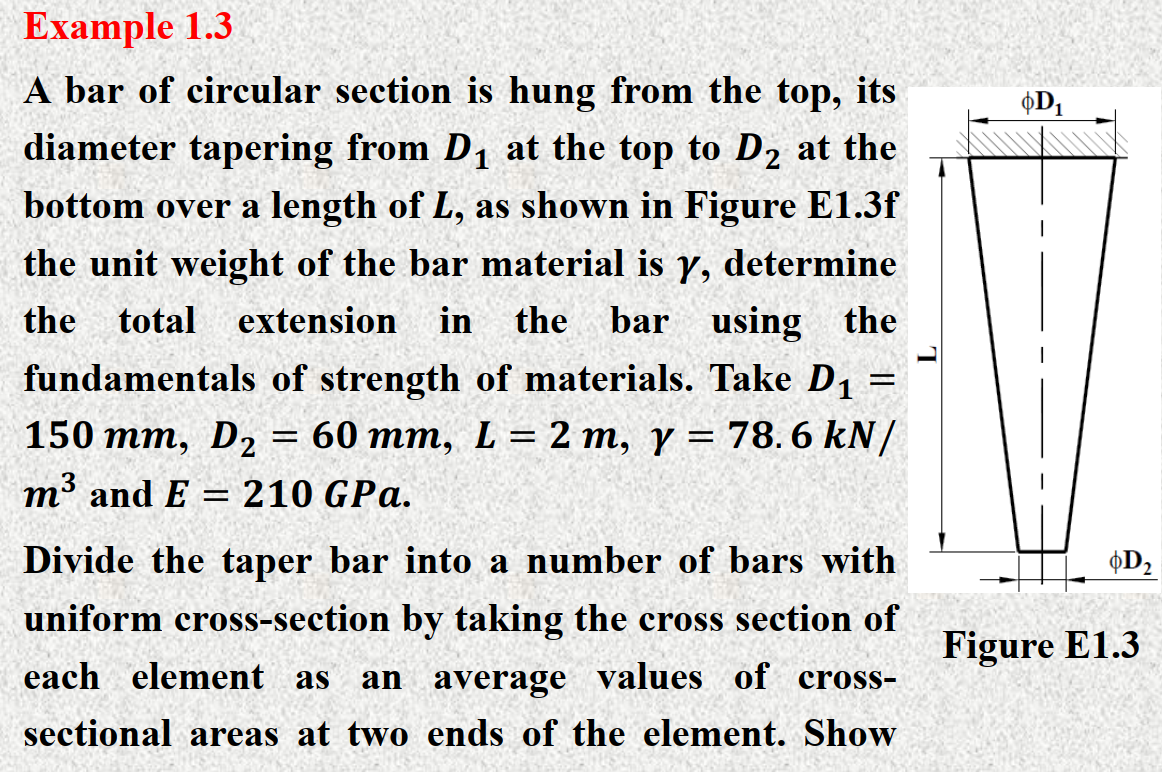

format shortE
L=2

L =      2


D1=0.15

D1 =    1.5000e-01


D2=0.06

D2 =    6.0000e-02


g=78.6e3

g =        78600


E=210e9

E =    2.1000e+11


Exact Value Calculation:

ev= g*(L^2)*((D1)^3+2*(D2)^3-3*(D1)*(D2)^2)/(6*E*D1*(D1-D2)^2)

ev =    4.4914e-07


Input the number of elements for finding the deflection using FEM

n=input("Enter the number of elements: ")

n =      3


Loop for finding the value of x,H and A required for each element

for m=1:1+n
    y(m)=(m-1)*L/n;
    D(m)=D2-(D2-D1)*y(m)/L
    A(m)=pi()*(D(m)^2)/4
end

D =    6.0000e-02


A =    2.8274e-03


D =    6.0000e-02   9.0000e-02


A =    2.8274e-03   6.3617e-03


D =    6.0000e-02   9.0000e-02   1.2000e-01


A =    2.8274e-03   6.3617e-03   1.1310e-02


D =    6.0000e-02   9.0000e-02   1.2000e-01   1.5000e-01


A =    2.8274e-03   6.3617e-03   1.1310e-02   1.7671e-02


Area average

for i=1:n
    Aa(i)=(A(i)+A(i+1))/2
end

Aa =    4.5946e-03


Aa =    4.5946e-03   8.8357e-03


Aa =    4.5946e-03   8.8357e-03   1.4491e-02


Taking initial deformation =0 and taking average of area at two ends for area of the element, we have,

td=0;
for m=1:n
    weight_below=0;
        for i=1:m-1
            weight_below=weight_below+g*Aa(i)*(L/n)
        end
    td(m)=g*(L/n)^2/(2*E)+weight_below*(L/n)/(Aa(m)*E)
end 

td =    8.3175e-08


weight_below =    2.4076e+02


td =    8.3175e-08   1.6968e-07


weight_below =    2.4076e+02


weight_below =    7.0375e+02


td =    8.3175e-08   1.6968e-07   2.3735e-07


total=sum(td)

total =    4.9020e-07


Calculation of error percentage

error_percentage=abs(total-ev)*100/ev

error_percentage =    9.1418e+00


fprintf("The total deformation is %.15f ",total);

The total deformation is 0.000000490202710 

fprintf("The percentage error is %f",error_percentage);

The percentage error is 9.141825

disp(error_percentage);

   9.1418e+00

